# AAE340 HW#6

## PROBLEM #3 (MATLAB)

numerically integrate and find the trajectories for an orbiter and probe mission for Jupiter.


$$\overset{\cdot \cdot }{r} -r{\left(\theta^{\cdot } \right)}^2 =\frac{-\mu \;}{r^2 }\;$$



$$r\;\theta^{\cdot \cdot } \;+2\overset{\cdot }{r} \;\theta^{\cdot } \;=0$$


### <3a>~<3d>

clear all
close all
clc

% Defining constants
Rj              = 71398;  % Radius of Jupiter [km]

% Orbiter Hyperbolic Trajectory
% Initial Conditions 
x0_oh           = [300*Rj, -6.4361, 0.4243341, 1.88518*10^(-8)];
% Time interval
t_span          = 0:2746100;
% Calling ode45
[t_oh, x_oh]    = ode45(@(t,x) dfcn(t,x), t_span, x0_oh);
r_oh            = x_oh(:,1);  % The r values
r_dot_oh        = x_oh(:,2);  % The r dot values
theta_oh        = x_oh(:,3);  % The theta values
theta_dot_oh    = x_oh(:,4);  % The theta dot values
% Limiting the indices to slice the vector up to r=4Rj
[val, idx] = min(r_oh); 
r_oh            = r_oh(1:idx);
t_oh            = t_oh(1:idx);
theta_oh        = theta_oh(1:idx);

% Probe Hyperbolic Trajectory
% Initial Conditions
x0_ph           = [300*Rj, -6.445716, 0.6642422, 9.309894*10^(-9)];
% Calling ode45
[t_ph, x_ph]    = ode45(@(t,x) dfcn(t,x), t_span, x0_ph);
r_ph            = x_ph(:,1);  % The r values
r_dot_ph        = x_ph(:,2);  % The r dot values
theta_ph        = x_ph(:,3);  % The theta values
theta_dot_ph    = x_ph(:,4);  % The theta dot values
% Limiting the indices to slice the vector up to r=Rj
[val, idx] = min(r_ph); 
r_ph            = r_ph(1:idx);
t_ph            = t_ph(1:idx);
theta_ph        = theta_ph(1:idx);

% Orbiter Elliptical Trajectory
% Initial Conditions
x0_oe           = [4*Rj, 0, pi, 1.035368*10^(-4)];
% Time interval
t_span = 1:17107200;
% Calling ode45
[t_oe, x_oe]    = ode45(@(t,x) dfcn(t,x), t_span, x0_oe);
r_oe            = x_oe(:,1);  % The r values
r_dot_oe        = x_oe(:,2);  % The r dot values
theta_oe        = x_oe(:,3);  % The theta values
theta_dot_oe    = x_oe(:,4);  % The theta dot values

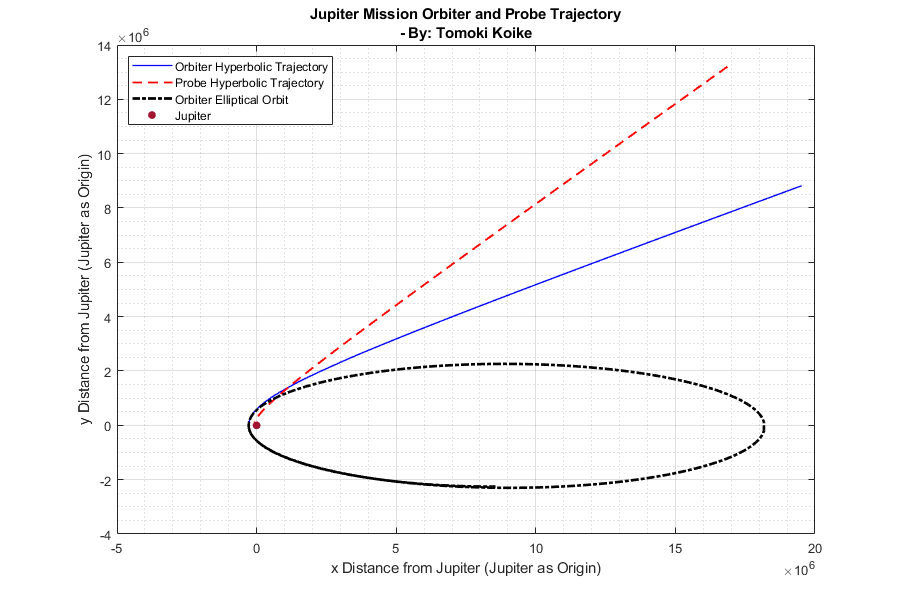

% Plotting
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(r_oh.*cos(theta_oh), r_oh.*sin(theta_oh), '-b', 'LineWidth',1)
title({'Jupiter Mission Orbiter and Probe Trajectory','- By: Tomoki Koike'})
xlabel('x Distance from Jupiter (Jupiter as Origin)')
ylabel('y Distance from Jupiter (Jupiter as Origin)')
hold on
plot(r_ph.*cos(theta_ph), r_ph.*sin(theta_ph), '--r', 'LineWidth', 1.4)
plot(r_oe.*cos(theta_oe), r_oe.*sin(theta_oe), '-.k', 'LineWidth', 2.0)
plot(0, 0, '.','Color','[0.6350 0.0780 0.1840]', 'MarkerSize', 20)
hold off
grid on
grid minor
box on
legend('Orbiter Hyperbolic Trajectory', 'Probe Hyperbolic Trajectory', ['Orbiter Elliptical' ...
    ' Orbit'], 'Jupiter', 'Location', 'northwest')

function dxdt = dfcn(t,x)
mu_J = 1.267*10^8;  % [km/s]
dxdt = zeros(4,1);   % Defining a zero vector to store the dxdt terms 
dxdt(1) = x(2);  % Derivative of x1 = x2
dxdt(2) = x(1)*x(4)^2 - mu_J/x(1)^2;  % Derivative of x2 
dxdt(3) = x(4);  % Derivative of x3 
dxdt(4) = -2*x(2)*x(4)/x(1);  % Derivative of x4
end  